clc;
clear all;
close all;

%%%%%%%%%%%%%%%%%%%%%%%%
% BLOCK I: Loading the dataset
%%%%%%%%%%%%%%%%%%%%%%%%
load Dataset_cell2cell.mat
Dataset = rmmissing(Dataset);

% Read the true distance among the cells
dist = table2array(Dataset(:, 1));

% Read the vesicles released by the immune cell
sequence = table2array(Dataset(:, 2:end));

% Calculating the slope
window = 2;
slope = sequence(:, window:end) - sequence(:, 1:end - window + 1);

% Calculating the amplitude and location of peaks
[peak, loc] = min(slope, [], 2);

% Conforming the new database with updated variable names
Dataset = array2table([dist, peak, loc], 'VariableNames', {'Var1', 'Feature1', 'Feature2'});

%%%%%%%%%%%%%%%%%%%%%%%%
% BLOCK II: Training the Neural Network
%%%%%%%%%%%%%%%%%%%%%%%%
rng("default") % For reproducibility
cvp1 = cvpartition(size(Dataset, 1), "Holdout", 1/10);
testTbl = Dataset(test(cvp1), :);
remainingTbl = Dataset(training(cvp1), :);
cvp2 = cvpartition(size(remainingTbl, 1), "Holdout", (3/10) / (1 - 1/10));
validationTbl = remainingTbl(test(cvp2), :);
trainTbl = remainingTbl(training(cvp2), :);

Mdl = fitrnet(trainTbl, "Var1", "Standardize", true, ...
    "ValidationData", validationTbl, 'ValidationPatience', 10, ...
    "Verbose", 1, ...
    "LayerSizes", [2], ...
    "Activations", 'sigmoid', 'LossTolerance', 1e-9);

|==========================================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  | Validation | Validation |
|            |            |            |            | Time (sec) | Loss       | Checks     |
|==========================================================================================|
|           1|    0.012043|    0.218233|    0.252241|    0.017488|    0.011937|           0|
|           2|    0.000325|    0.004363|    0.087316|    0.011176|    0.000337|           0|
|           3|    0.000299|    0.004758|    0.004193|    0.014999|    0.000314|           0|
|           4|    0.000169|    0.003115|    0.040902|    0.004844|    0.000184|           0|
|           5|    0.000157|    0.001291|    0.009061|    0.009775|    0.000168|           0|
|           6|    0.000150|    0.002356|    0.010411|    0.002411|    0.000157|           0|
|           7|    0.000142|    0.004091|    0.012697|    0.000375|    


%%%%%%%%%%%%%%%%%%%%%%%%
% BLOCK III: Feature Importance Calculations
%%%%%%%%%%%%%%%%%%%%%%%%
% Baseline loss (mean squared error) on validation data
baselineLoss = loss(Mdl, validationTbl);
predictorNames = trainTbl.Properties.VariableNames(2:end);

% Permutation importance
permImportanceScores = zeros(2, 1);
for i = 1:2
    tempTbl = validationTbl;
    tempTbl.(predictorNames{i}) = tempTbl.(predictorNames{i})(randperm(height(tempTbl)));
    permImportanceScores(i) = loss(Mdl, tempTbl) - baselineLoss;
end

% Gaussian Noise Addition
noiseImportanceScores = zeros(2, 1);
for i = 1:2
    tempTbl = validationTbl;
    stdDev = std(tempTbl.(predictorNames{i}));
    noise = randn(height(tempTbl), 1) * stdDev * 0.1;
    tempTbl.(predictorNames{i}) = tempTbl.(predictorNames{i}) + noise;
    noiseImportanceScores(i) = loss(Mdl, tempTbl) - baselineLoss;
end

% Mean Importance
meanImportanceScores = zeros(2, 1);
for i = 1:2
    tempTbl = validationTbl;
    meanValue = mean(tempTbl.(predictorNames{i}));
    tempTbl.(predictorNames{i}) = repmat(meanValue, height(tempTbl), 1);
    meanImportanceScores(i) = loss(Mdl, tempTbl) - baselineLoss;
end

% Shapley values
explainer = shapley(Mdl, trainTbl, 'QueryPoints', Dataset);


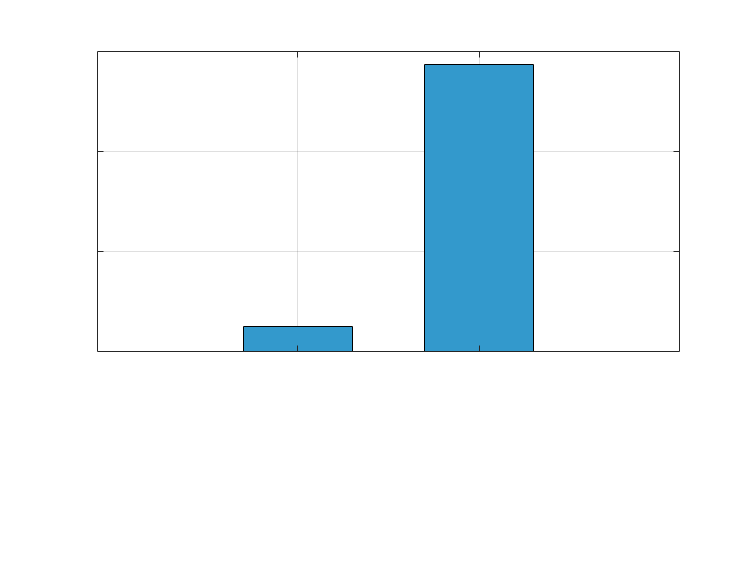


%%%%%%%%%%%%%%%%%%%%%%%%
% BLOCK IV: Combined Plotting
%%%%%%%%%%%%%%%%%%%%%%%%
fontsize=32;
close all;
% figure('Position', [100, 100, 1200, 800]);
%tiledlayout(2, 3, 'TileSpacing', 'Compact', 'Padding', 'Compact'); % Adjusted to 2 rows and 3 columns

% Permutation Importance Plot
% nexttile(1);
figure;
bar(permImportanceScores, 'FaceColor', [0.2, 0.6, 0.8], 'BarWidth', 0.6);
%title('Permutation Importance', 'FontSize', 22, 'FontWeight', 'normal');
ylabel('Performance Loss', 'FontSize', fontsize,'Interpreter','latex');
xticks(1:2);
xticklabels({'Peak amplitude', 'Peak-time','FontSize', fontsize});
%xtickangle(45);
%set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');
set(gca, 'FontSize', fontsize,'TickLabelInterpreter', 'latex'); % Increase font size for X-tick labels
grid on;

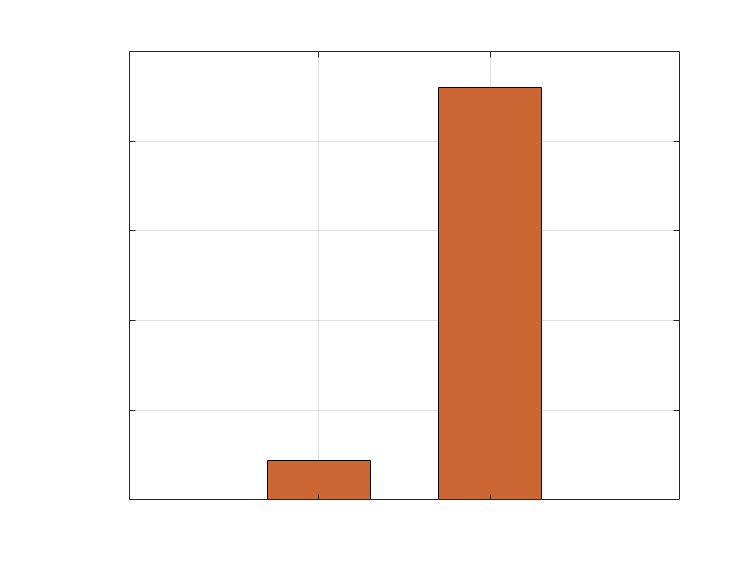


% Gaussian Noise Importance Plot
figure;
% nexttile(2);
bar(noiseImportanceScores, 'FaceColor', [0.8, 0.4, 0.2], 'BarWidth', 0.6);
%title('Gaussian Noise Addition', 'FontSize', 22, 'FontWeight', 'normal');
ylabel('Performance Loss', 'FontSize', fontsize,'Interpreter','latex');
xticks(1:2);
xticklabels({'Feature1', 'Feature2','FontSize', fontsize});
%xtickangle(45);
%set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');
set(gca, 'FontSize', fontsize, 'TickLabelInterpreter', 'latex'); % Increase font size for X-tick labels
grid on;

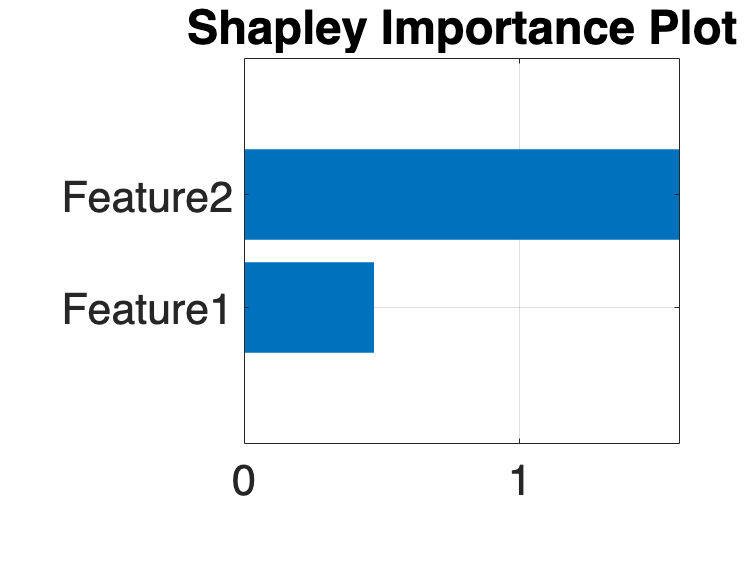


% % Mean Importance Plot
% nexttile(3);
% bar(meanImportanceScores, 'FaceColor', [0.4, 0.8, 0.2], 'BarWidth', 0.6);
% %title('Mean Importance per Predictor', 'FontSize', fontsize, 'FontWeight', 'normal');
% ylabel('Increase in Loss', 'FontSize', fontsize,'Interpreter','latex');
% xticks(1:2);
% xticklabels({'Feature1', 'Feature2','FontSize', fontsize});
% xtickangle(45);
% %set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');
% set(gca, 'FontSize', fontsize, 'TickLabelInterpreter', 'latex'); % Increase font size for X-tick labels
% grid on;

% Shapley Mean Absolute
% nexttile(4); % Positioned below Permutation Importance
figure;
plot(explainer);
%title('Mean Absolute Shapley', 'FontSize', fontsize, 'FontWeight', 'normal');
xlabel('Mean Absolute Shapley Values', 'FontSize', fontsize,'Interpreter','latex'); % Increased font size for X-axis
ylabel('Predictor', 'FontSize', fontsize,'Interpreter','latex'); % Increased font size for Y-axis
set(gca, 'FontSize', fontsize); % Increase font size for X-tick labels

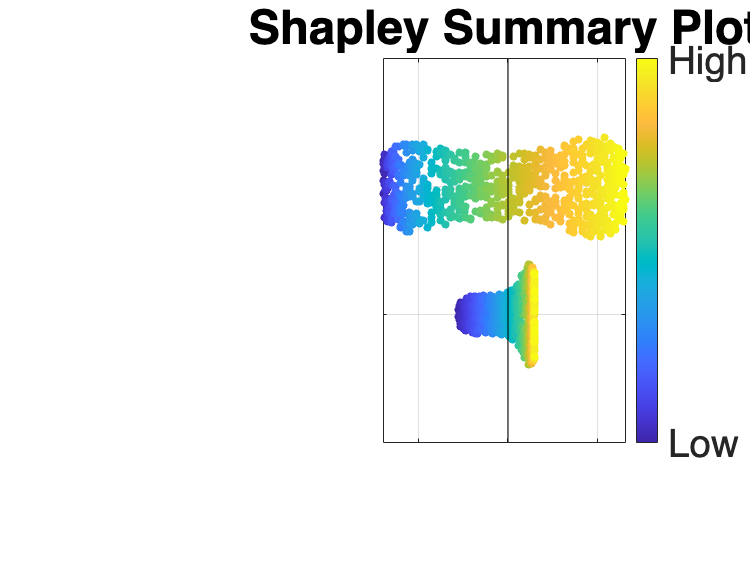



% Shapley Swarm Chart
% nexttile(5); % Positioned below Gaussian Noise Addition
figure;
swarmchart(explainer);
%xlabel('Shapley Values', 'FontSize', fontsize,'Interpreter','latex'); % Increased font size for X-axis
%ylabel('Predictor', 'FontSize', fontsize,'Interpreter','latex'); % Increased font size for Y-axis
%set(gca, 'FontSize', fontsize); % Increase font size for X-tick labels

xlabel('Shapley Values', 'FontSize', fontsize, 'Interpreter', 'latex');
ylabel('Predictor', 'FontSize', fontsize, 'Interpreter', 'latex');

% Update axes font size
ax = gca;
set(ax, 'FontSize', fontsize);

% Set custom Y-tick labels instead of 'Feature1', 'Feature2', etc.
yticks(1:2); % assuming you have 2 features, adjust if more
yticklabels({'Peak amplitude', 'Peak-time'}); % replace with your names

% Optional: use LaTeX interpreter for Y labels too
set(ax, 'TickLabelInterpreter', 'latex');

% Grid on
grid on;